# Tema 7

**Pb 1.** Implementati o rutina pentru calculul valorilor polinomului de interpolare Hermite cu noduri duble, dandu-se punctele in care se face evaluarea, nodurile, valorile functiei si ale derivatei in noduri.

**Pb 2. **Reprezentati pe acelasi grafic f si polinomul sau de interpolare Hermite.

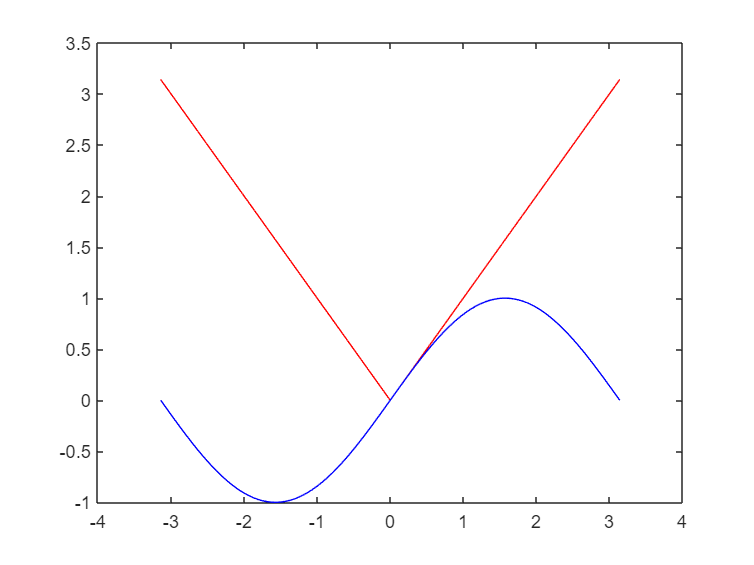

x = [0 pi/4 pi/2 3*pi/2];
y = sin(x);
fderiv = cos(x);

new_nodes = -pi : 0.0001 : pi;
hermite_results = Hermite_multiplePoints(x, y, fderiv, new_nodes);

plot(new_nodes, hermite_results, 'red');
hold on;
tmp = linspace(-pi, pi, 100);
results = sin(tmp);
plot(tmp, results, 'blue');
hold off;

**Pb 3. **Scrieti o rutina care reprezinta grafic o cubica parametrica Hermite (o curba care trece prin doua puncte date si are in acele puncte tangente date).

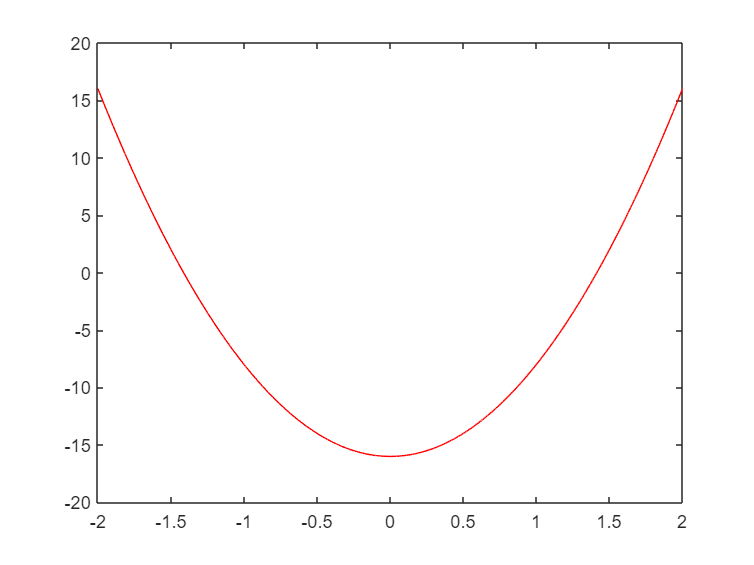

% f(x) = x^4
x = [-2 2];
y = [16 16]; 
fderiv = [-32 32];

new_nodes = -2 : 0.0001 : 2;
results = Hermite_multiplePoints(x, y, fderiv, new_nodes);

plot(new_nodes, results, 'red');

**Pb 1'. **Pentru f(x) = e^x si nodurile de interpolare 0, 1, 2, aproximati f(0:25) prin interpolare Hermite si comparati rezultatul cu cel obtinut prin interpolare Lagrange. Dati o delimitare a erorii. Comparati cu rezultatul furnizat de software-ul utilizat.

x = 0.25;
fprintf("1' ____________________")

1' ____________________

hermite_val = Hermite([0 1 2], [exp(0) exp(1) exp(2)], [exp(0) exp(1) exp(2)], x)

hermite_val = 1.2500

lagrange_val = calculateLagrangePolynomial([0 1 2], [exp(0) exp(1) exp(2)], x)

lagrange_val = 1.1528

real_val = exp(x)

real_val = 1.2840

err_hermite = abs(real_val - hermite_val)

err_hermite = 0.0340

err_lagrange = abs(real_val - lagrange_val)

err_lagrange = 0.1313

**Pb 2'. **Utilizati valorile date mai jos pentru a aproxima sin 0:34 utilizand interpolarea Hermite. Dati o delimitare a erorii si comparati-o cu eroarea exacta. Adaugati datele pentru nodul x = 0:33 si refaceti calculele.

x = [0.3, 0.32, 0.35];
y = sin(x);
fderiv = cos(x);
xx = [0.34];

fprintf("2' ____________________")

2' ____________________

hermite_val = Hermite(x, y, fderiv, xx)

hermite_val = 0.3337

real_val = sin(xx)

real_val = 0.3335

err = abs(sin(xx) - hermite_val);



x = [0.3, 0.32, 0.33, 0.35];
y = sin(x);
fderiv = cos(x);
xx = [0.34];

fprintf("____________________")

____________________

hermite_val = Hermite(x, y, fderiv, xx)

hermite_val = 0.3337

real_val = sin(xx)

real_val = 0.3335

err = abs(sin(xx) - hermite_val);

**Pb 3'. **Un automobil care se deplaseaza pe un drum drept este cronometrat in mai multe puncte. Datele de observatie se dau in tabela de mai jos. Utilizati interpolarea Hermite pentru a prevedea pozitia si viteza automobilului la momentul t = 10.

timp = [0 3 5 8 13];
distanta = [0 225 383 623 993];
viteza = [75 77 80 74 72];
noduri = [10];

fprintf("3' ____________________")

3' ____________________

[d, dH] = Hermite_withDerivative(timp, timp, viteza, noduri);
distanta2 = d

distanta2 = 2.2084e+03

viteza2 = dH

viteza2 = 2.1368e+03